# Forward Kinematics 

[⇦ Return to the navigation page](matlab:open('./HelperFunctions/Navigation.mlx'))

In the [previous section](matlab:open('./DH_Parameters.mlx')), we used DH Parameters and transformation matrices to transform one coordinate system into another based on the definition of the link/joint parameters. In this section, we will focus on calculating a robot's forward kinematics. Traditionally, this process uses kinematic equations to specify the joint angles and observe the location of the end-effector. In this script, we'll continue using DH parameters and transformation matrices to yield the same result as the traditional process.

        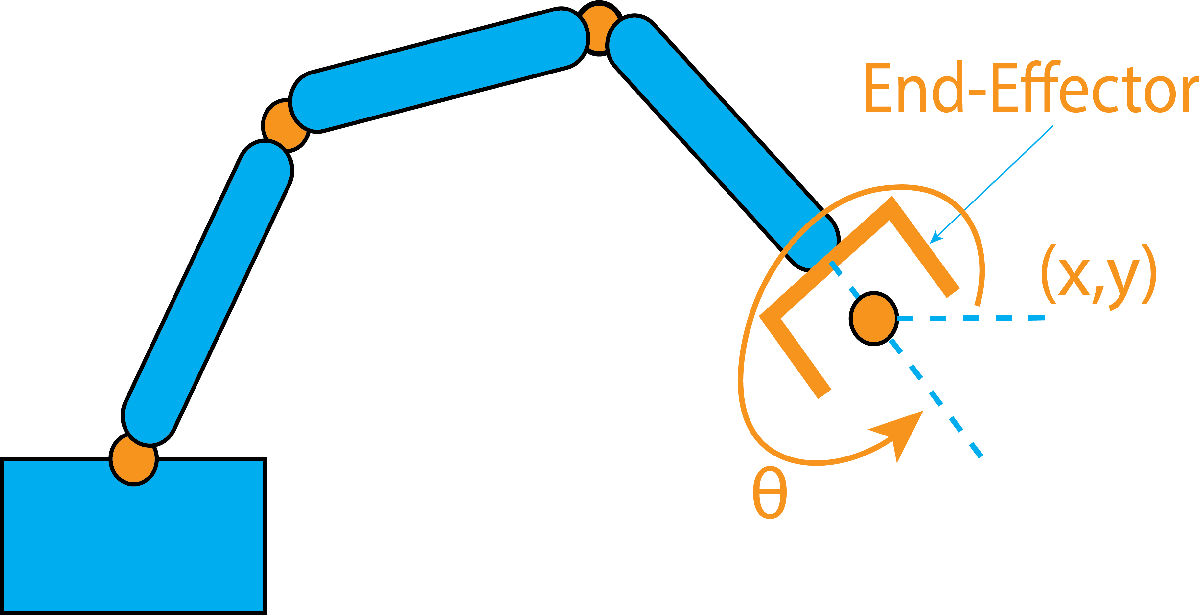

In this script, you will calculate a robot's forward kinematics to determine the end-effector's location. 

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if they run out of order.

## Forward Kinematics Background

The goal of forward kinematics [1] is to obtain the position and orientation of a robot's end-effector by utilizing the robot's joint angles, thus defining the robot's motion path. Because of this, the robot's motion is centered around each joint. Each joint rotates individually, creating arc trajectories for the robot. For example, pictured below is a 3-joint robot. Rotating about joint 1 controls the movement of joints 2 and 3, creating an arc movement. Rotating about joint 2 controls the movement of joint 3, and so on, if there are more joints. When you combine the changes of these joint angles, you can determine the final placement of the end-effector.

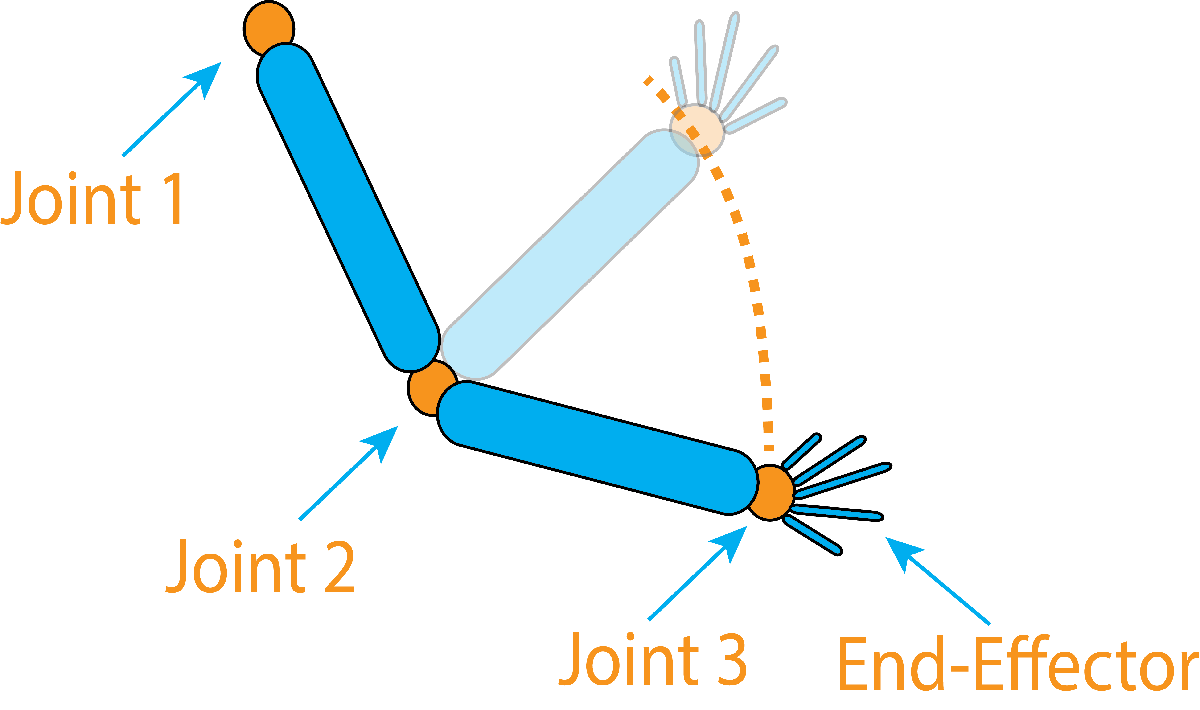

**Activity**. Practice forward kinematics! First, sit down in a chair at a table. Next, hold your arm stiffly next to your body. Consider your shoulder as Joint 1, your elbow as Joint 2, and your wrist as Joint 3. Now, try and pick up an object on the table by only rotating about the joints in your arm as you move.

### Assigning Frames

The first step in performing forward kinematics is to assign coordinate frames to the robotic links. We accomplished [assigning frames from the previous script by using DH parameters](matlab:open('.\DH_Parameters.mlx')), as seen in the following figure. We will do the same here. The next step focuses on calculating the transformation matrix of adjacent frames from each link. We will walk through each of these steps to visualize a simplified version of the links/joints of the robot.

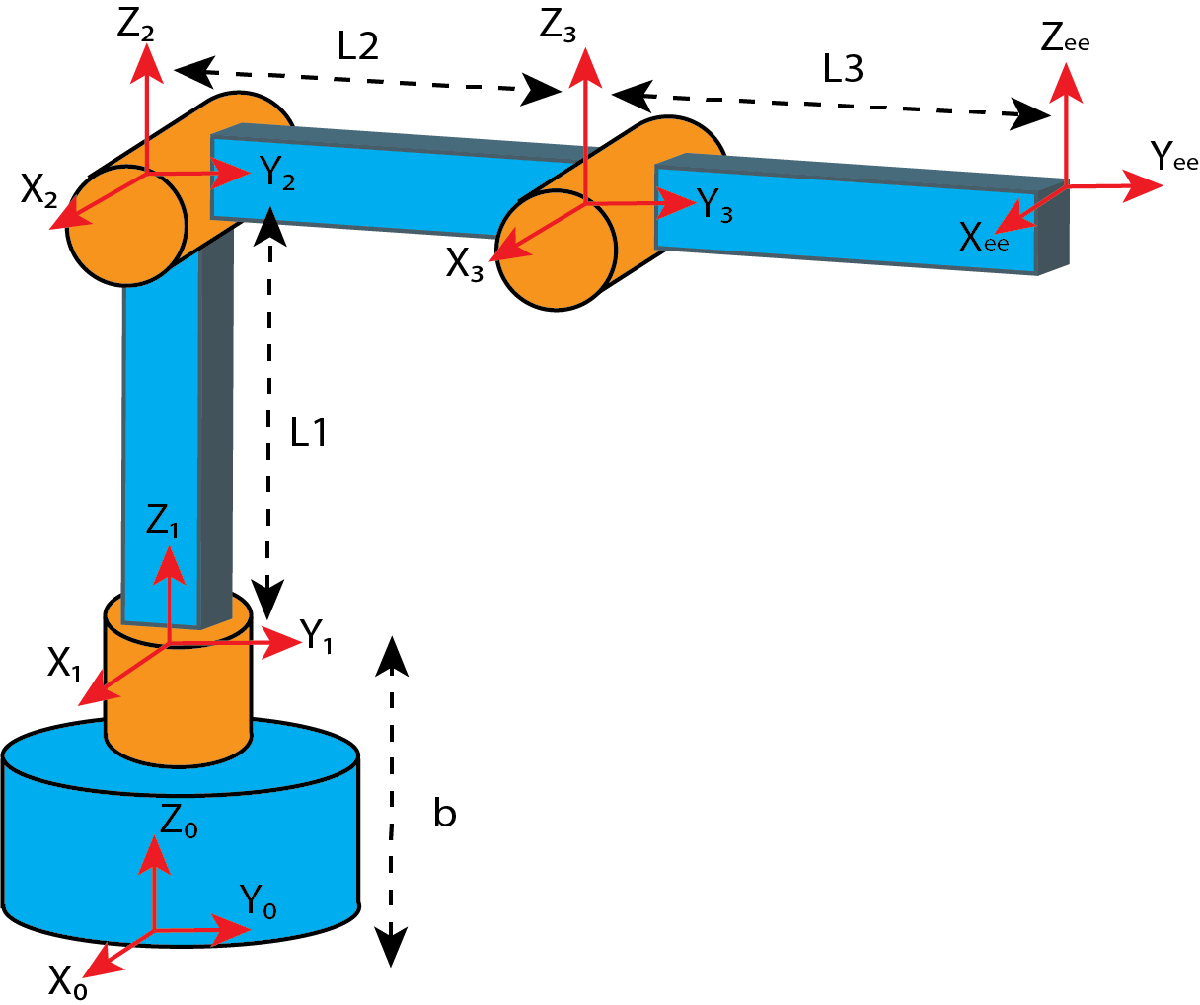

** Demonstration**. Let's specify our own joint angles to control a Puma 560 [3] 6DOF robot with only revolute (rotational) joints. We will create a default set [as seen in the DH Parameters script](matlab:open('./DH_Parameters.mlx')) and then modify the joint angles later to see how the robot arm moves:

#### 
$$\textrm{Puma560}\;=\left\lbrack \begin{array}{cccc}
a & \alpha  & d & \theta \\
0 & 90 & 0 & 270\\
0\ldotp 4318 & 0 & 0 & 90\\
0\ldotp 0203 & -90 & 0\ldotp 15005 & 0\\
0 & 90 & 0\ldotp 4318 & 0\\
0 & -90 & 0 & 0\\
0 & 0 & 0 & 0
\end{array}\right\rbrack$$


% Definition of the link lengths and joint angles (units in Meters and Degrees)
a1 = 0;        alpha1 = 90;     d1 = 0;          t1 = 270;  
a2 = 0.4318;   alpha2 = 0;      d2 = 0;          t2 = 90;  
a3 = 0.0203;   alpha3 = -90;    d3 = 0.15005;    t3 = 0;  
a4 = 0;        alpha4 = 90;     d4 = 0.4318;     t4 = 0;
a5 = 0;        alpha5 = -90;    d5 = 0;          t5 = 0;  
a6 = 0;        alpha6 = 0;      d6 = 0;          t6 = 0;

### Transformation Matrices of Adjacent Frames

Each frame's transformation matrix specifies the orientation and position of each joint. While we primarily care about the transformation matrix of the end-effector frame, we will also calculate the matrices for the other frames. This will help to define the location of the other joints in space. We can multiply the transformation matrices of each joint to determine the end-effector location as follows:

#### 
$$T_0^n =T_0^1 \times T_1^2 \times T_2^3 \times \ldotp \ldotp \ldotp {\times \;T}_{n-1}^n$$


This multiplication gives us the transformation matrix of the end-effector:

% Defined transformation matrices for adjacent frames using DH parameters
T01 = dh_param(t1,d1,alpha1,a1); 
T12 = dh_param(t2,d2,alpha2,a2);
T23 = dh_param(t3,d3,alpha3,a3);
T34 = dh_param(t4,d4,alpha4,a4);
T45 = dh_param(t5,d5,alpha5,a5);
T56 = dh_param(t6,d6,alpha6,a6);

% Calculate Transformation matrix for the end-effector frame
 
T0ee = T01*T12*T23*T34*T45*T56

As a result, we have the following transformation matrix for the end-effector broken down into its useful parts: 

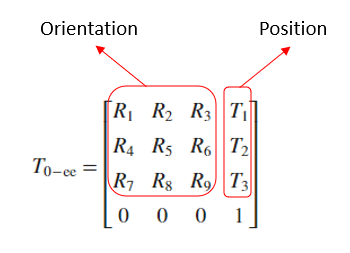

The three columns of the rotation matrix (R1-R9) represent the rotation of the end-effector on a particular axis. For example, if the end-effector were rotating about the X-axis, the rotation components would be defined by the 1st column of the rotation matrix (R1, R4, R7). The translation vector (T1-T3) defines the position in space where the end-effector is located. For convenience, the output for the orientation and position matrices from the T0-ee transformation matrix is printed out below:

% Display output of transformation matrix orientation and position
Orientation = T0ee(1:3,1:3)
Position = T0ee(1:3,end)

  **Pro-tip**. Recalling the [previous section](matlab:open('./DH_Parameters.mlx')), the rotation and translation matrices are a part of the transformation matrix. In this case, those matrices can also be observed as the orientation and position definitions of the end-effector, T0-ee, respectively.

### Visualizing the Robot

Finally, let's take the calculated points of each joint and plot them to visualize what the 6DOF robot arm looks like. The blue dot represents the end-effector, and the black dots represent the other joints in the figure below. If you open the View tab, select Datatips, and click the blue dot. You will notice that the end-effector's X, Y, and Z points will be shown and match that of the T0-ee position vector displayed above. 

  **Try**. Adjust the sliders below to observe the arc movements around each robot joint. Start by adjusting the sliders for Joint Angle 1 to $270 \degree$, Joint Angle 2 to $90 \degree$, and Joint Angle 3 to $0 \degree$.

% Sliders to adjust joint angles of robot arm
th1 = 0; 
th2 =0; 
th3 =0; 
th4 =0; 
th5 =0; 
th6 =0; 

% Defined transformation matrices for adjacent frames using DH parameters
T01 = dh_param(th1,d1,alpha1,a1); 
T12 = dh_param(th2,d2,alpha2,a2);
T23 = dh_param(th3,d3,alpha3,a3);
T34 = dh_param(th4,d4,alpha4,a4);
T45 = dh_param(th5,d5,alpha5,a5);
T56 = dh_param(th6,d6,alpha6,a6);

% Transformation matrix of each joint in with respect to the base (This is the T0ee equation split up into individual parts)
T02 = T01*T12; 
T03 = T02*T23; 
T04 = T03*T34; 
T05 = T04*T45; 
T06 = T05*T56;
Tb = {T01;T02;T03;T04;T05;T06};

% Define x,y,z points for each joint of the 6DOF robot
O1 = T01(1:3,end); 
O2 = T02(1:3,end); 
O3 = T03(1:3,end); 
O4 = T04(1:3,end); 
O5 = T05(1:3,end); 
O6 = T06(1:3,end); 

% Define X,Y,Z points for robot joints
X = [0 O1(1) O2(1) O3(1) O4(1) O5(1) O6(1)];
Y = [0 O1(2) O2(2) O3(2) O4(2) O5(2) O6(2)];
Z = [0 O1(3) O2(3) O3(3) O4(3) O5(3) O6(3)];

% Plot joints and linkages of robot
plot3(X,Y,Z,'-ko','LineWidth',1,"MarkerFaceColor",'black')
hold on
plot3(X(7),Y(7),Z(7),'bo',"LineWidth",1,"MarkerFaceColor",'blue')
axR = gca;

Recall from the [DH Parameters module](matlab:open('./DH_Parameters.mlx')) that the robot model in the figure appears only to display 4DOF. However, the robot has 6DOF. Three rotational DOFs exist in the end-effector (blue dot) for the X, Y, and Z axes. The other joints shown (black dots) have one rotational DOF each. This makes up the total 6DOF. To see the last two DOFs at the end effector, check the "Show Coordinate Frames" checkbox below after adjusting the slider values for Joint Angles 4,5 and 6.

cfFlag = false;
% Plot the coordinate Frames
if cfFlag
    quiverSize = max([range(axR.XLim) range(axR.YLim) range(axR.ZLim)]/5); %#ok<UNRCH> 
    for ii = 1:length(X)-1
        TX = Tb{ii}*[1;0;0;0];
        TY = Tb{ii}*[0;1;0;0];
        TZ = Tb{ii}*[0;0;1;0];
        qX = quiver3(X(ii+1), Y(ii+1), Z(ii+1), TX(1), TX(2), TX(3), quiverSize ,'SeriesIndex', 1, 'LineWidth',2);
        qY = quiver3(X(ii+1), Y(ii+1), Z(ii+1), TY(1), TY(2), TY(3), quiverSize ,'SeriesIndex', 2, 'LineWidth',2);
        qZ = quiver3(X(ii+1), Y(ii+1), Z(ii+1), TZ(1), TZ(2), TZ(3), quiverSize ,'SeriesIndex', 3, 'LineWidth',2);
    end
    % Add legend for axis
    legend(axR,{'','','X','Y','Z'});
end
hold off

% Label the figure and adjust view
title('PUMA 560 6DOF Robot Arm defined by Forward Kinematics')
xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)')
xlim([-1 1]); ylim([-1 1]); zlim([-1 1])
view([148 20])
grid

 **Reflect**.  Use the "Show Coordinate Frames" checkbox to see the frames on each joint. The end-effector (blue dot) is rotating about the Z-axis. Which column of the rotation matrix represents its rotation about the Z-axis? 

 **Exercise 1. **Starting from the current robot position, what combination of joint angles will show the robotic arm to appear flat? Please select one option. Hint: Go back and interact with the sliders above to see if you can make the robot arm appear flat, as shown below: 

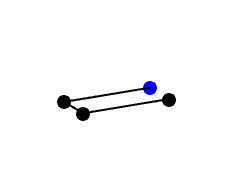

exerciseSol1(...
    A = false, ...
    B = false, ...
    C = false, ...
    D = false);

  **Pro-tip**. Remember that each preceding joint is the parent joint for the following joints. If you change joint angle 1, it affects joints 2-6. And if you change joint angle 2, it affects joints 3-6 and so on. Think about the order of each joint before changing them to achieve the configuration you want.

## Randomized Manipulator Trajectory Planning 

Trajectory planning is finding a time series of successive joint angles that allows for movement from a starting configuration to a desired configuration while avoiding collisions. In randomized trajectory planning, rather than defining the time series of the joint angles, they can be randomly generated within the bounds of the robot. Providing a series of joint angles to the simulated model will calculate the transformation matrices (forward kinematics) required to move the robot arm into the desired position. We will explore a robot model in 3D space and observe how it moves when there is a defined set of joint angles to follow.

### Import Robot Model 

** Application. **Simulate trajectory planning for a built-in robot model in [Simulink](https://www.mathworks.com/products/simulink.html). For this example, we will use the KINOVA [JACO](https://assistive.kinovarobotics.com/product/jaco-robotic-arm)®, a 3-fingered 6 DOF robot with a non-spherical wrist.

 

% Load Kinova robot into the MATLAB base workspace
robotToTest = loadrobot("kinovaJacoJ2N6S300",DataFormat="column")

### Trajectory Definition 

Starting with trajectory planning [2], we will utilize the following built-in MATLAB functions: [homeConfiguration](https://www.mathworks.com/help/robotics/ref/rigidbodytree.homeconfiguration.html) and [randomConfiguration](https://www.mathworks.com/help/robotics/ref/rigidbodytree.randomconfiguration.html). These functions work on robotic [rigidBodyTree](https://www.mathworks.com/help/robotics/ref/rigidbodytree.html) objects like the KINOVA robot. This method will define a trajectory profile through a set of waypoints. Each waypoint represents a change in joint angle for each joint. The home configuration will provide a starting set of waypoints, while the random configuration will provide an ending set of waypoints:

% Print out Home Configuration
[HomeJointAngles,Units,NameList] = JointFun(robotToTest,"home");
homeConfig = table(HomeJointAngles,Units,'RowNames',NameList)
% Print out Random Configuration
[RandJointAngles,~,~] = JointFun(robotToTest,"random");
randConfig = table(RandJointAngles,Units,'RowNames',NameList)
% Because the home and random configurations share the same NameList and Units, 
% we can reuse those variables when populating the table for the random configuration. 
% Utilizing the "~" option in the JointFun function allows us to omit those outputs.

 **Note**. You may have noticed nine joints defined in the home and random tables. However, it was specified in the application that there are only six joints (DOF) in this robot. This is because the last three joints represent movement in the three fingers of the end-effector. They do not affect the movement of the robot arm itself.

### View Robot Model 

In Simulink, we will use a [Trapezoidal Velocity Profile Trajectory](https://www.mathworks.com/help/robotics/ref/trapezoidalvelocityprofiletrajectory.html) block to generate a time profile over a set of waypoints (joint angles). In our case, they will generate random waypoints that will drive the manipulator accordingly. Defining the joint angles, or position ($q$), of the robot joints will also determine the velocity ($\dot{q} \;\textrm{or}\;\textrm{qd}$) and acceleration ($\ddot{q} \;\textrm{or}\;\textrm{qdd}$) of the joints. With this information, the manipulator model can compute the joint torque required to execute the robot's motion. 

 

% Open Simulink model of Kinova robot
open_system("Models/ManipulatorTrajectoryPlanning_Randomized.slx")

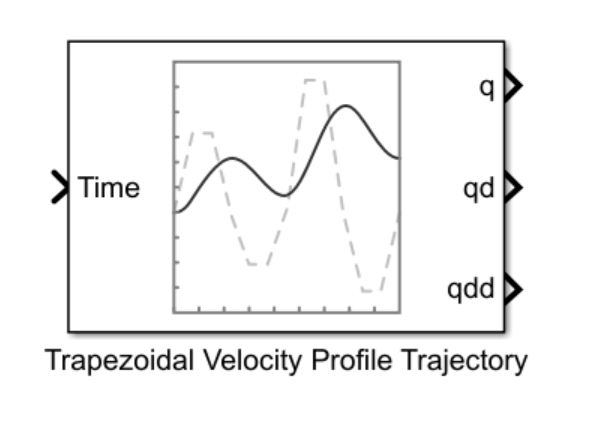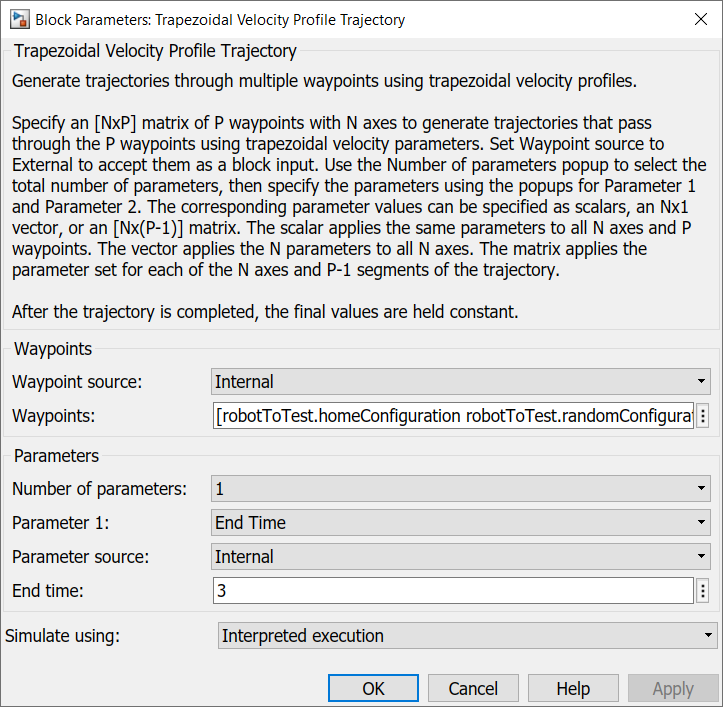

### Simulate Robot Model

Upon simulating the model, we can visualize the robot motion in [Mechanics Explorer](https://www.mathworks.com/help/sm/ref/mechanicsexplorer-app.html) and plot the torque at each robotic joint using a [Simulink Scope](https://www.mathworks.com/help/simulink/slref/scope.html) in the model.

 

% Run the Simulink model of the Kinova robot
sim("Models/ManipulatorTrajectoryPlanning_Randomized.slx","StopTime","5");

  **Pro-tip. **You can view the robot configurations by entering ***robotToTest.homeConfiguration*** and ***robotToTest.randomConfiguration ***in the command window in MATLAB. 

 **Warning**: When you enter the command to display the random configuration, MATLAB will generate a new set of joint angles (in radians) every time.

 **Pro-tip. **Once the Mechanics Explorer is open, you can run a new randomized configuration of the manipulator simulation by selecting the run button   in the toolstrip. Simulations in Simulink are dynamic (time-based). This means that you are observing the manipulator in different orientations and positions over a period of time.

 **Exercise 2. **The current waypoint definition in the Trapezoidal Velocity Profile Trajectory block shows the robot **fully vertical at its home configuration** and then follows a random trajectory. It is expressed in the block as a 3x1 "Waypoints" vector: 

As detailed above, both homeConfig and randomConfig are 9x1 vectors. Define a new trajectory that will take the manipulator from a vertical position to a **right angle** and back to vertical again. This means your "Waypoints" input in the block will also be a 3x1 vector. The right angle must start at joint #2. Create a new variable called **newConfig** **(9x1)** to define your new waypoint that defines the right angle movement. Set the "End Time" in the Trapezoidal Velocity Profile Trajectory block to 2. Click the run button once you have updated your "Waypoints" input. Enter your answer for newConfig in the field below.

 **Note 1. **The joint angle configurations are displayed in degrees for ease of reading. The trajectory block expects an input of radians to compute the correct movement. If you create a vector for newConfig in degrees, convert them to radians before executing your code.

 **Note 2. **Remember there are nine joints total. Be sure to leave joints 7-9 at a value of zero.

newConfig = [];

 **Exercise 3. **Create a new "Waypoints" input that starts at the home position, moves randomly, and ends at a defined position. The specified end position is: 

Rerun the model and examine the [scope blocks](https://www.mathworks.com/help/simulink/slref/scope.html) at the top level of the model labeled "End-Effector Position" and "Robot Joint Torque." Upon opening the scopes, find the toolstrip and use the zoom tool   to estimate the values for the following questions. You can use the scale tool   to return to the original view of the plots. What is the end-effector's starting and ending position (X, Y, Z)? During the manipulator motion, which joints exert the minimum and maximum magnitude of torque?

 **Pro-tip. **Explore the Simulink model to see how it works!

Starting Position of End-Effector:

0;
0;
0;

End Position of End-Effector:

0;
0;
0;

Finding the Torque in the Joints:

"No Selection";
"No Selection";

 **Reflect**. Think back to introductory physics. Why does the joint you selected exert the largest amount of torque?

## Next Steps

This script covered the fundamentals of performing forward kinematics using DH parameters. The purpose of this is to find the orientation and position of the end-effector using the joint angles. We will now go in the reverse direction in the next script, focusing on inverse kinematics, using the orientation and position of the end-effector to determine the joint angles.

## Definitions

Forward Kinematics - The process of obtaining the end-effector's position given other joint parameters. (↑ Return to Text)

Waypoints - The route a robot follows based on the mapping of points (joint angles). (↑ Return to Text)

Degrees of Freedom (DOF) - The number of independent variables that define a mechanical system's possible positions or motions in space.  (↑ Return to Text)

## Further Exploration

- [Library of Robot Models for Simulation](https://www.mathworks.com/matlabcentral/fileexchange/98714-robotics-system-toolbox-robot-library-data)

## References

[1] (n.d.). *Forward Kinematics*. Robotics and ROS Learning. [https://www.rosroboticslearning.com/forward-kinematics](https://www.rosroboticslearning.com/forward-kinematics) (↑ Return to Text)

[2] (n.d.). *Robot Trajectory Planning*. Wikibooks. [https://en.wikibooks.org/wiki/Robotics/Navigation/Trajectory_Planning](https://en.wikibooks.org/wiki/Robotics/Navigation/Trajectory_Planning) (↑ Return to Text)

[3] P. I. Corke and B. Armstrong-Helouvry, "A search for consensus among model parameters reported for the PUMA 560 robot," *Proceedings of the 1994 IEEE International Conference on Robotics and Automation*, San Diego, CA, USA, 1994, pp. 1608-1613 vol.2, doi: 10.1109/ROBOT.1994.351360. (↑ Return to Text)

[⇦ Return to the navigation page](matlab:open('./HelperFunctions/Navigation.mlx'))

## Local Helper Functions

If you want to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function T = dh_param(theta,d,alpha,a)
    % This function generates a transformation matrix T depending on input 
    % dh parameters: theta, d, alpha and a
    arguments
        theta (1,1) double {mustBeNumeric}
        d (1,1) double {mustBeNumeric}
        alpha (1,1) double {mustBeNumeric}
        a (1,1) double {mustBeNumeric}
    end

    % Calculating sin-cos for theta and alpha (Converts Deg to Rad before
    % calculation
    St = sin(deg2rad(theta));
    Ct = cos(deg2rad(theta));

    Sa = sin(deg2rad(alpha));
    Ca = cos(deg2rad(alpha));

    % Calculate matrix T
    T = [Ct -St*Ca St*Sa  a*Ct;...
         St Ct*Ca  -Ct*Sa a*St;...
         0  Sa     Ca     d   ;...
         0  0      0      1  ];
end

function [JointAngles,Units,NameList] = JointFun(object,str)
    % This function is to simplify the code needed for displaying the
    % information for a robot's joint angles in a meaningful way.
    arguments
        object (1,1) rigidBodyTree {mustBeA(object,"rigidBodyTree")}
        str (1,1) string {mustBeText}
    end

    % Branch Statement for producing home or random joint angles in degrees
    if str == "home"
        JointAngles = object.homeConfiguration.*(180/pi);
    elseif str == "random"
        JointAngles = object.randomConfiguration.*(180/pi);
    end

    % Creating vector of units and names for joint angles
    jointCount = length(JointAngles);
    Units = cell(jointCount,1);
    NameList = cell(jointCount,1);
    for ii = 1:jointCount
        Units{ii,1} = 'deg';
        NameList{ii,1} = ['Joint ' num2str(ii)];
    end
end

function exerciseSol1(opts)
    % Provides solution for Exercise 1
    arguments
        opts.A (1,1) logical
        opts.B (1,1) logical
        opts.C (1,1) logical
        opts.D (1,1) logical
    end

    if (opts.C)
        disp("Correct!")
    elseif ~any([opts.A opts.B opts.C opts.D])
        disp("Please select one. Which option works?")
    else % [opts.A opts.B opts.D]
        disp("Incorrect.")
    end
end